afsana = load("D:\green tea Result produce\3 March and onward\Afsana_S5.mat")

afsana = struct with fields:
    s11a30: [14975×2 timetable]
    s11a60: [14975×2 timetable]
      s11b: [14950×2 timetable]
    s12a30: [14975×2 timetable]
    s12a60: [14975×2 timetable]
      s12b: [14950×2 timetable]
    s13a30: [14975×2 timetable]
    s13a60: [14975×2 timetable]
      s13b: [14975×2 timetable]
    s14a30: [14975×2 timetable]


ecg_new = afsana.s11a30.Dev1_ai2

ecg_new =     1.2316
    1.3387
    1.3258
    1.3645
    1.4844
    1.4857
    1.4535
    1.4199
    1.4135
    1.4225


ppg = afsana.s11a30.Dev1_ai3

ppg =     2.3164
    2.2919
    2.2919
    2.2958
    2.2996
    2.3035
    2.3074
    2.3112
    2.3138
    2.3177


time = afsana.s11a30.Time(2550:5001)

time = 2452×1 duration array
   10.196 sec
     10.2 sec
   10.204 sec
   10.208 sec
   10.212 sec
   10.216 sec
    10.22 sec
   10.224 sec
   10.228 sec
   10.232 sec
   10.236 sec
    10.24 sec
   10.244 sec
   10.248 sec
   10.252 sec
   10.256 sec
    10.26 sec
   10.264 sec
   10.268 sec
   10.272 sec
   10.276 sec
    10.28 sec
   10.284 sec
   10.288 sec
   10.292 sec
   10.296 sec
     10.3 sec
   10.304 sec
   10.308 sec
   10.312 sec


ecg = afsana(1)

ecg = struct with fields:
    s11a30: [14975×2 timetable]
    s11a60: [14975×2 timetable]
      s11b: [14950×2 timetable]
    s12a30: [14975×2 timetable]
    s12a60: [14975×2 timetable]
      s12b: [14950×2 timetable]
    s13a30: [14975×2 timetable]
    s13a60: [14975×2 timetable]
      s13b: [14975×2 timetable]
    s14a30: [14975×2 timetable]


ecg_duration = length(ecg)/(250*60)

ecg_duration = 6.6667e-05

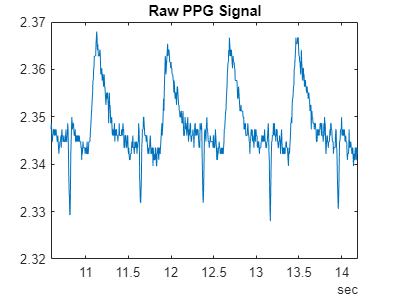

% Loading PPG variables
s1_raw_ppg = ppg(2550:5001);
%time = M15L_O.Time;
plot(time, s1_raw_ppg); %sample rate =250, t = 15 sec
title("Raw PPG Signal");
xlim([time(100,1) time(1000,1)]);

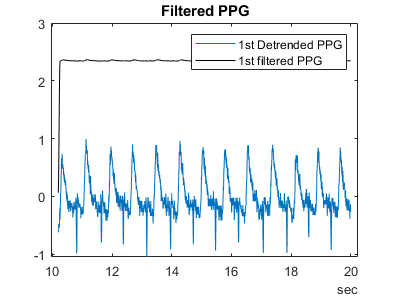

%%low-pass & FIR
fc = 0.5;
fs = 250;
wn= 2*fc/fs;
bhi = fir1(14,wn,'low',chebwin(15,30));
f_ppg = filter(bhi,1,s1_raw_ppg);
n_f_ppg = normalize(s1_raw_ppg, 'range', [-1 1]);

figure
detrendedData = detrend(n_f_ppg,6);
plot(time, detrendedData)
hold on
plot(time, f_ppg, 'k')
title("Filtered PPG")
legend("1st Detrended PPG", "1st filtered PPG")
hold off

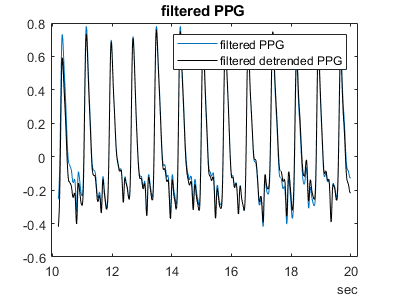



%% Smoothing PPG
z = n_f_ppg;            %(500:3000,1);
t = time;               %(500:3000,1);
y = smoothdata(z,'gaussian','SmoothingFactor',0.26,'SamplePoints',t);


figure
plot(t, y)
hold on
title("filtered PPG ")
detrendedData = detrend(y,4);
plot(t, detrendedData, 'k')
legend("filtered PPG", "filtered detrended PPG")

%% PPG derivative 1
temptime = time((1: length(time) -1), 1);
 
d1 = diff(detrendedData); %corrected 
fs1 = 250;
d1 = lowpass(d1,5,fs1,'Steepness',0.6,'StopbandAttenuation',60);
d1 = smoothdata(d1,'gaussian','SmoothingFactor',0.26,'SamplePoints',temptime);
d1 = normalize(d1, 'range', [-1, 1]);
figure
% plot(temptime, d1, 'k', "LineWidth", 0.5)
% hold on
plot(t, detrendedData, 'm', "LineWidth", 0.5)
%xlim([time(1000,1) time(2000,1)])
hold on
%% PPG derivative 2
d2 = diff(d1);
new_temptime = temptime((1: length(temptime) -1), 1);
d2 = lowpass(d2,2,fs1,'Steepness',0.5,'StopbandAttenuation',60);
%d2 = detrend(d2);
d2 = smoothdata(d2,'gaussian','SmoothingFactor',0.26,'SamplePoints',new_temptime);

d2 = normalize(d2, 'range', [-1, 1]);

plot(new_temptime, d2)
legend("PPG", "PPG Derivitive1", "PPG Derivitive2")

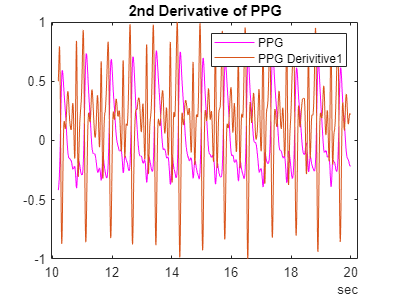

title("2nd Derivative of PPG") 

%% Loading ECG variables
s1_raw_ecg = ppg

s1_raw_ecg =     2.3164
    2.2919
    2.2919
    2.2958
    2.2996
    2.3035
    2.3074
    2.3112
    2.3138
    2.3177


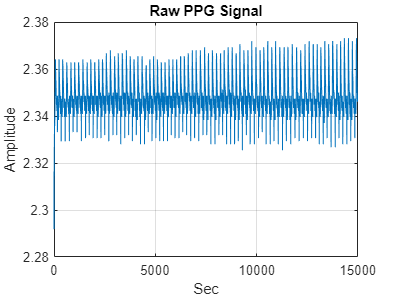

figure
plot(s1_raw_ecg, "LineWidth", 0.5)
grid on;
%sample rate =250, t = 15 sec
title("Raw PPG Signal")
xlabel("Sec")
ylabel("Amplitude")

%set(gca, 'XTickLabels', 0:0.004:59.9);

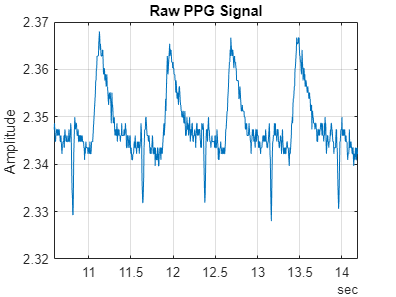

%% Loading ECG variables
s1_raw_ppg = ppg(2550:5001);;
figure
plot(time, s1_raw_ppg, "LineWidth", 0.5)
grid on;
%sample rate =250, t = 15 sec
title("Raw PPG Signal");
ylabel("Amplitude");

xlim([time(100,1) time(1000,1)])

xlim([duration(0,0,10.59)...
      duration(0,0,14.19)])
ylim('auto')